# Image Analysis

- Understand how images are represented

- Kosher image manipulations

- Understand basic image manipulations

-     filter

-     thresholds

-     segmentation operations

## Understand how images are represented

Images are represented in grids. Below is an example of a 5x5 image grid. 

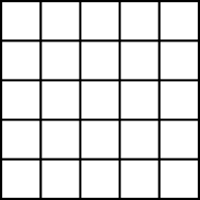

When you start analyzing your image, you should know

- the dynamic range of measurement (bit depth)

- spatial scales. To what do you pixels correspond to?

- how was the image constructed? Correlations in space from optics ([point spread function](https://en.wikipedia.org/wiki/Point_spread_function) (PSF), which describes the response of an imaging system to a point source), for other reasons? And collecting sources, such as [CMOS pixel sensor](https://en.wikipedia.org/wiki/Active_pixel_sensor), [charged coupled device ](https://en.wikipedia.org/wiki/Charge-coupled_device)(CCD), or scanning microscope?

- temporal scales, and [global vs. rolling shutter](https://www.bhphotovideo.com/explora/video/tips-and-solutions/rolling-shutter-versus-global-shutter) (see below and movie)

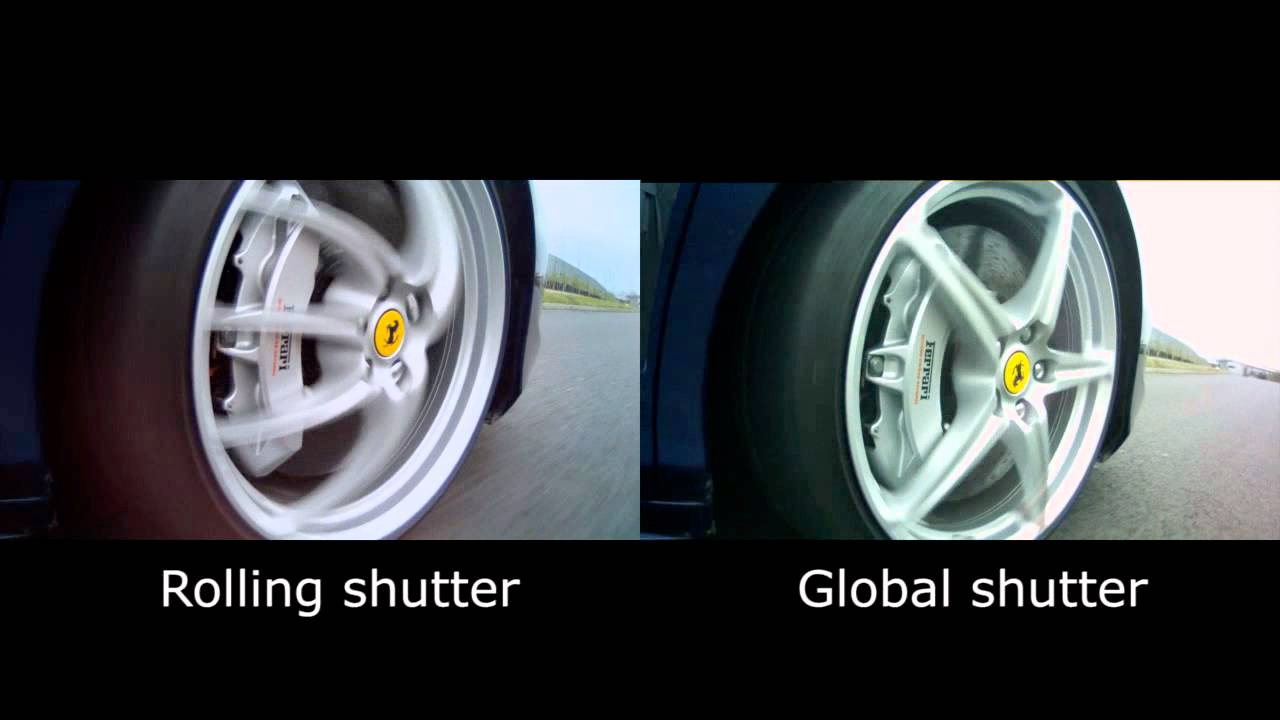

In addition, the following issues are cases you should look out for:

- saturation = lost data

- [Aliasing](https://en.wikipedia.org/wiki/Aliasing) in space or in time. Aliasing is an effect that causes different signals to become indistinguishable when sampled. Therefore, if you have to digitilize your image, perform this once, instead of multiple digital conversions. You rather integrate analog. 

- color cameras are not your friend, due to the color filter used: [Bayer filters](https://en.wikipedia.org/wiki/Bayer_filter), reinterpolation, etc

- interpolation and downsampling. For downsampling, make sure you average first over a certain area.

- [Gamma correction](https://en.wikipedia.org/wiki/Gamma_correction) in images/visualizing (see below).

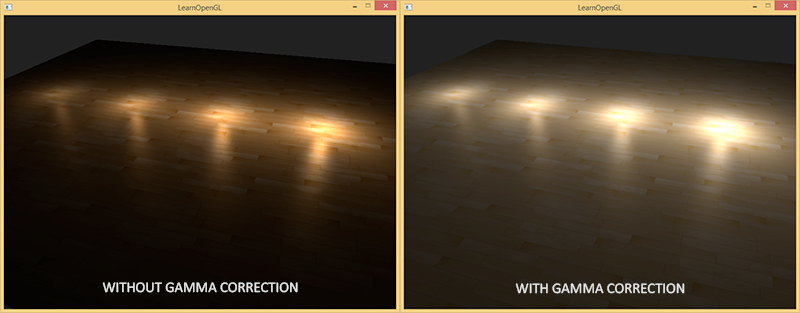

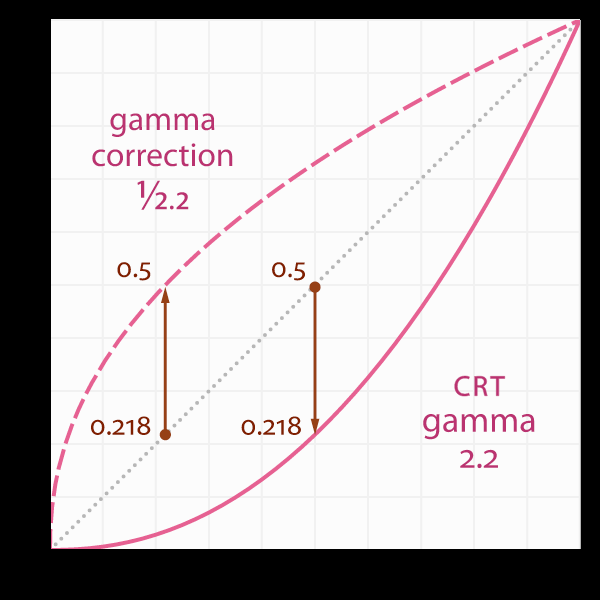 

## Kosher image manipulation

Kosher means that you perform your image manipulations in such a way that you can undo these changes. Manipulations such as cutting, pasting, and moving stuff is **not **kosher. Also, gamma changes are probably not so kosher. Kosher manipulations are

- changing contrast (without clipping)

- changing mean (without clipping)

Image data is like any other data and you can apply all the techniques learned in the previous sessions. The advantage of image analysis is that we often know what to look for in image data, as these are objects that persist in space and time.

## Understanding Basic Image Manipulation

In the example below, we will cover the following topics:

- histograms

- median and mean filters; other filters

- finding objects: thresholds, edge detection, binary operations, wathershed, segmentation, "region-props"

- computing intensity over time

%% load in the data
load('probeEpochData.mat');
load('croppedMovie.mat');

%% plot some basics
figure;
subplot(2,1,1);
plot(probeEpochData);
ylabel('stimulus type');
xlabel('frame number');

subplot(2,1,2);
imagesc(squeeze(ims(:,:,1)));
colormap('gray');
axis image;
title('first image');
xlabel('pixel');
ylabel('pixel');

%% now, let's play ourselves a movie

figure;
for ii=1:size(ims,3)
    imagesc(ims(:,:,ii));
    set(gca,'clim',[0 max(ims(:))]);
    colormap('gray');
    title(['frame number = ' num2str(ii)]);
    axis image;
    drawnow;
end

%% let's just look at the a corner of the pixels

ims(1:10,1:5,1)

%% plot out a histogram of pixel values to see bit depth, and look for saturation

figure;
hist(ims(:),200);
set(gca,'yscale','log');
xlabel('pixel value');
ylabel('count through movie');


Find the mean image of the entire stack, and find the std image over the entire stack. This will make things a bit clearer, since individual movie frames are pretty noisy

imMean = mean(ims,3);
imSTD = std(ims,[],3);

figure; 
subplot(2,1,1);
imagesc(imMean);
title('mean');
colormap('gray');
subplot(2,1,2);
imagesc(imSTD);
colormap('gray');
title('std');


Just for fun, plot the variance against the mean. If this plot is flat, then this would be a constant input of fluorescence. This shouldn't be the case, because neurons should respond by turning on and off, which is what causes the variance.

% there's extra variability from the response here...
figure;
subplot(2,1,1);
plot(imMean(:),imSTD(:).^2,'r.');
xlabel('mean pixel value');
ylabel('var pixel value');
subplot(2,1,2);
plot(imMean(:),imSTD(:).^2./imMean(:),'r.');
xlabel('mean pixel value');
ylabel('var/mean');

%% now, let's start looking at what we can do here...
imMean(1:10,1:5) % check out the raw, mean pixel values

The numbers are now much larger. This is 2PE scope images obtained with a [photomultiplier](https://en.wikipedia.org/wiki/Photomultiplier) (PMT), which makes it hard to collect images. This is why the *imMean *values are larger than the previous plot. 

% and now check out a histogram of those values
figure;
hist(ims(:),200);
xlabel('pixel value');
ylabel('count');
set(gca, 'yscale','log');

## *Linear filtering*

[Convolution](https://en.wikipedia.org/wiki/Convolution) is an operation on two functions (*f* and *g*); it produces a third function, that is typically viewed as a modified version of one of the original functions, giving the integral of the pointwise multiplication of the two functions as a function of the amount that one of the original functions is translated. Basically, it is taking repeated dot-products to obtain the signal. This is a technique to *get rid of noise *and emphasizes the signal. In MatLab, we use the *conv2 *function. 

A = ones(10); % can also make more complicated filters -- round or gaussian. try one out here?
imf = conv2(imMean,A,'same');

figure;
subplot(2,1,1); colorbar;
imagesc(imMean);
set(gca,'clim',[0 max(imMean(:))]);
colormap('gray');
axis image;
subplot(2,1,2); colorbar;
imagesc(imf);
set(gca,'clim',[0 max(imf(:))]);
colormap('gray');
axis image;

The following plot shows the image as if it there is shadowing on it. The *gx* will give the vertical edges.

%% highlight x-direction gradients!
gx = [1 0 -1; 2 0 -2; 1 0 -1];

imf = conv2(imMean,gx,'same');
figure;
subplot(2,1,1);
imagesc(imMean);
set(gca,'clim',[0 max(imMean(:))]);
colormap('gray');
axis image;
subplot(2,1,2);
imagesc(imf);
set(gca,'clim',[min(imf(:)) max(imf(:))]);
colormap('gray');
axis image;

The *gy *will give the horizontal edges

%% highlight all edges/gradients
gx = [1 0 -1; 2 0 -2; 1 0 -1];
gy = [1 2 1; 0 0 0; -1 -1 -1];

imf = sqrt(conv2(imMean,gx,'same').^2 + conv2(imMean,gy,'same').^2);
figure;
subplot(3,1,1);
imagesc(imMean);
set(gca,'clim',[0 max(imMean(:))]);
colormap('gray');
axis image;
subplot(3,1,2);
imagesc(imf);
set(gca,'clim',[0 max(imf(:))]);
colormap('gray');
axis image;
subplot(3,1,3); %this plots the very low quality of edges
imagesc(log(imf));
set(gca,'clim',[0 max(log(imf(:)))]);
colormap('gray');
axis image;



## *Nonlinear filtering*

Instead of averaging, what about nonlinear filtering?

% first, let's just mess with gamma.
imMean1 = imMean/max(imMean(:));
G = [0.25 0.5 2 4];
figure;
subplot(5,1,1);
imagesc(imMean1);
set(gca,'clim',[0 1]);
colormap('gray');
axis image;

for ii=1:length(G)
    subplot(5,1,ii+1);
    imagesc(imMean1.^G(ii));
    ylabel(['\gamma = ' num2str(G(ii))]);
    set(gca,'clim',[0 1]);
    colormap('gray');
    axis image;
end
% note: screens all do this automatically

The [gamma correction](https://www.cgsd.com/papers/gamma_intro.html) controls the overall  brightness of an image. Images which are not properly corrected can look either bleached out, or too dark. Trying to reproduce colors accurately also requires some knowledge of gamma. Varying the amount of gamma  correction changes not only the brightness, but also the ratios of red to green to blue. In the previous example, with a $\gamma$ of 4 you emphasize the dark pixels. The gamma correction is mainly for visualization, you're not affecting the image. 

%% side note: color maps and limits make a huge difference
figure;
h1 = subplot(3,1,1);
imagesc(imMean);
set(gca,'clim',[0 max(imMean(:))]);
colormap(h1, 'gray');
axis image
colorbar;

h2 = subplot(3,1,2);
imagesc(imMean);
set(gca,'clim',[0 max(imMean(:))/5]);
colormap(h2,'gray');
axis image
colorbar;

subplot(3,1,3);
imagesc(imMean);
axis image
colorbar;

## *Filters: Median filter*

Instead of taking the mean value of a pixel set, you take the median value. When your noise is Gaussian, you take the *mean value;* if your noise is non-Gaussian, you will take the *median value.* 

%% very useful way to filter out salt-and-pepper noise: median filter
imsel = ims(:,:,160);
figure;
subplot(2,1,1);
imagesc(imsel);
set(gca,'clim',[0 max(imsel(:))]);
axis image;
% pause;
subplot(2,1,2);
imagesc(medfilt2(imsel,[3 3]));
set(gca,'clim',[0 max(imsel(:))]);
axis image;

## *Thresholding*

[Image thresholding ](https://en.wikipedia.org/wiki/Thresholding_(image_processing))is a simple, yet effective, way of partitioning an image into a foreground and background. This image analysis technique is a type of image segmentation that isolates objects by  converting grayscale images into binary images. Image thresholding is most effective in images with high levels of contrast.

%% let's try thresholding this thing to see what we find
ims10 = ims > 1000;

% check out the movie
figure;
for ii=1:size(ims10,3)
    imagesc(ims10(:,:,ii));
    set(gca,'clim',[0 1]);
    colormap('gray');
    title(['frame number = ' num2str(ii)]);
    drawnow;
end

%% now, how to select regions of interest for further analysis?

im10 = (imMean > 500);
% note: you can find a good, rational threshold by k-means clustering or LDA!

figure;
subplot(2,1,1);
imagesc(imMean);
set(gca,'clim',[0 max(imMean(:))]);
colormap('gray');
axis image;
subplot(2,1,2);
imagesc(im10);
set(gca,'clim',[0 1]);
colormap('gray');
axis image;

## *Erosion and dilation*

[Erosion](https://en.wikipedia.org/wiki/Erosion_(morphology)) and[ dilation](http://usually uses a structuring element for probing and expanding the shapes contained in the input image.) depends on the neighbouring pixels. In **erosion**, you take the white regions and make these smaller. In this way, you get rid of small white blobs in bw and create smoother edges. In **dilation**, you use a structured element for probing and expanding the shapes contained in the input image. Basically, you make the blobs bigger. 

%% now, some useful operations for binary images
im10d = im10;
figure;
for ii=1:5
    subplot(5,1,ii);
    im10d = imerode(im10d,ones(3));
    imagesc(im10d);
    set(gca,'clim',[0 1]);
    colormap('gray');
    axis image;
end

im10d = im10;
figure;
for ii=1:5
    subplot(5,1,ii);
    im10d = imdilate(im10d,ones(3));
    imagesc(im10d);
    set(gca,'clim',[0 1]);
    colormap('gray');
    axis image;
end

## *Watershedding*

[Watershed](https://en.wikipedia.org/wiki/Watershed_(image_processing)) is a transformation defined on a grayscale image. The watershed transformation treats the image it operates upon like a topographic map, with the brightness of each point representing its height, and finds the lines that run along the tops of ridges. Basically, the image will be segmented in regions. 

%% watershedding to find regions...
L = watershed(-conv2(imMean,ones(9)));
figure;
subplot(2,1,1);
imagesc(imMean);
axis image;
subplot(2,1,2);
imagesc(L);
axis image;

%% go back to binary and find all the connected objects
cc = bwconncomp(im10,ones(3));
cc
R = zeros(size(im10));
for ii=1:cc.NumObjects
    R(cc.PixelIdxList{ii})=ii;
end
figure;
imagesc(R);
axis image;

%% get region props gives a structure array with properties
pp = regionprops(im10); % many options here -- see website
pp

Here we are looking at the fluorescence of each cell is over time.

for ii=1:cc.NumObjects
    for tt=1:size(ims,3)
        temp = ims(:,:,tt);
        ff(ii,tt) = mean(temp(cc.PixelIdxList{ii}));
        % QUESTION: if you are measuring photons, is equal weighting the
        % way to go here, or should you weight some pixels more?
    end
end
figure;
plot(ff');
xlabel('time (frames)');
ylabel('fluorescence (au)');

You don't want to weight by intensities when it is a Poisson process, like here. In this case, you want to integrate. 

Next, we are going to average over all the regions we found:

%% plot up a nice figure of the results
figure;
subplot(2,1,1);
plot(probeEpochData);
ylabel('stimulus type');
subplot(2,1,2); hold on;
plot(mean(ff,1),'k');
plot(squeeze(mean(mean(ims,2),1)),'r');
legend('ROIs','full screen');
xlabel('time (frames)');
ylabel('fluorescence (au)');

You can also select an ROI by hand, using *roipoly*. 

%% just to check on the background... since we're using a light stimulus
figure;
imagesc(imMean);
M = roipoly;
idx = find(M);
for tt=1:size(ims,3)
    temp = ims(:,:,tt);
    bg(tt) = mean(temp(idx));
end

figure;
subplot(2,1,1);
plot(probeEpochData);
ylabel('stimulus type');
subplot(2,1,2);
plot(bg);
xlabel('time (frames)');
ylabel('background intensity');
% clearly some bleedthrough